#  Kinematics for parol6

DH table

% Clear workspace and command window
clear; clc;

% Define symbolic variables for the joint angles
syms q1 q2 q3 q4 q5 q6 ez real 

% Define the DH parameters from the table
% Columns are: [alpha, a, theta, d]
% Note: Constants in degrees are converted to radians (e.g., -90 deg = -pi/2)
DH = [
   -pi/2,   0,      q1-pi/2,    110.5;   % i = 1
   -pi/2,   23.42,  q2 - pi/2,  0;       % i = 2
    0,      180,    q3,         0;       % i = 3
   -pi/2,   43.5,   q4,         176.35;  % i = 4
    pi/2,   0,      q5,         0;       % i = 5
   -pi/2,   0,      q6,         0;       % i = 6
    0,      0,     -pi/2,       ez     % i = ee
];
disp("Visualising DH table")

Visualising DH table


vpa(DH,4)

$$ans = \left(\begin{array}{cccc} -1.571 & 0 & q_{1}-1.571 & 110.5\\ -1.571 & 23.42 & q_{2}-1.571 & 0\\ 0 & 180.0 & q_{3} & 0\\ -1.571 & 43.5 & q_{4} & 176.4\\ 1.571 & 0 & q_{5} & 0\\ -1.571 & 0 & q_{6} & 0\\ 0 & 0 & -1.571 & \mathrm{ez} \end{array}\right)$$

# Forward Kinematics

T0_ee = eye(4);
T_prev_i = cell(1, 7);
T_0_i = cell(1, 6);


for i = 1:size(DH, 1)
    alpha = DH(i, 1);
    a     = DH(i, 2)/1000;
    theta = DH(i, 3);
    d     = DH(i, 4)/1000;
    
    % Standard DH Transformation Matrix Formula
    T_i = [ cos(theta),             -sin(theta),              0,            a;
            sin(theta)*cos(alpha),   cos(theta)*cos(alpha),  -sin(alpha),  -d*sin(alpha);
            sin(theta)*sin(alpha),   cos(theta)*sin(alpha),   cos(alpha),   d*cos(alpha);
            0,                       0,                       0,            1];
            
    % Simplify the current matrix to evaluate sin/cos of constants (like pi/2)
    T_i = simplify(T_i);
    T_prev_i{i} = T_i;
    
    % Post-multiply to accumulate the total transformation
    T0_ee = T0_ee * T_i;
    T_0_i{i} = simplify(T0_ee);
end

T0_ee = simplify(T0_ee);
disp('Final Transformation Matrix T0_ee:');

Final Transformation Matrix T0_ee:


disp(T0_ee);

## Test FK here

q1_val = 0; q1_val = deg2rad(q1_val);
q2_val = 0; q2_val = deg2rad(q2_val);
q3_val = 0; q3_val = deg2rad(q3_val);
q4_val = 0; q4_val = deg2rad(q4_val);
q5_val = 0; q5_val = deg2rad(q5_val);
q6_val = 0; q6_val = deg2rad(q6_val);


res = subs (T0_ee,[q1,q2,q3,q4,q5,q6, ez],[q1_val, q2_val, q3_val, q4_val, q5_val, q6_val, 89]);
res = double (res)

res =     1.0000         0         0         0
         0    1.0000         0    0.3340
         0         0    1.0000    0.2888
         0         0         0    1.0000



R = res(1:3, 1:3);
angles_rad = rotm2eul(R, 'XYZ');

% Extract individual angles in radians
Rx_rad = angles_rad(1);
Ry_rad = angles_rad(2);
Rz_rad = angles_rad(3);

% Convert back to degrees if needed
Rx_deg = rad2deg(Rx_rad);
Ry_deg = rad2deg(Ry_rad);
Rz_deg = rad2deg(Rz_rad);

fprintf('Rx: %.2f deg, Ry: %.2f deg, Rz: %.2f deg\n', Rx_deg, Ry_deg, Rz_deg);

Rx: -0.00 deg, Ry: 0.00 deg, Rz: -0.00 deg


# Jacobian

J = sym(zeros(6, 6));
% Filling in the angular velocity part first

J(4:6,1) = T_0_i{1}(1:3,3);
J(4:6,2) = T_0_i{2}(1:3,3);
J(4:6,3) = T_0_i{3}(1:3,3);
J(4:6,4) = T_0_i{4}(1:3,3);
J(4:6,5) = T_0_i{5}(1:3,3)

$$J = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{4}\right)+\sin\left(q_{4}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right) & 0\\ 1 & 0 & 0 & -\sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right) & 0\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{4}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)-\cos\left(q_{4}\right)\,\sin\left(q_{1}\right) & 0 \end{array}\right)$$

disp("Angular Part filled, now linear part")

Angular Part filled, now linear part


J(4:6,6) = T_0_i{6}(1:3,3)

$$J = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{4}\right)+\sin\left(q_{4}\right)\,\sigma_{1} & \sin\left(q_{5}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sigma_{1}\right)-\cos\left(q_{5}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)\\ 1 & 0 & 0 & -\sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{4}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{5}\right)-\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{4}\right)\,\sigma_{2}-\cos\left(q_{4}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{5}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-\sin\left(q_{5}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}$$



% Filling in linear velocity part
P_ee = T0_ee(1:3,4);
J(1:3,1) = cross(T_0_i{1}(1:3,3), P_ee - T_0_i{1}(1:3,4));
J(1:3,2) = cross(T_0_i{2}(1:3,3), P_ee - T_0_i{2}(1:3,4));
J(1:3,3) = cross(T_0_i{3}(1:3,3), P_ee - T_0_i{3}(1:3,4));
J(1:3,4) = cross(T_0_i{4}(1:3,3), P_ee - T_0_i{4}(1:3,4));
J(1:3,5) = cross(T_0_i{5}(1:3,3), P_ee - T_0_i{5}(1:3,4));
J(1:3,6) = cross(T_0_i{6}(1:3,3), P_ee - T_0_i{6}(1:3,4));
disp("Linear part filled")

Linear part filled


J = simplify(J)


% --- 1. SYMBOLIC CHECK (Linear Part Only) ---
q_vars = [q1, q2, q3, q4, q5, q6];
P_ee = T0_ee(1:3, 4); % Extract Cartesian position

% Use MATLAB's built-in symbolic derivative
J_linear_matlab = simplify(jacobian(P_ee, q_vars))


% Subtract your manual derivation from MATLAB's
diff_linear = simplify(J(1:3, :) - J_linear_matlab);
disp('Symbolic Difference (Manual vs MATLAB). Should be all 0s:');

Symbolic Difference (Manual vs MATLAB). Should be all 0s:


disp(diff_linear);

$$\left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_numeric = double(subs(J, [q1, q2, q3, q4, q5, q6], ...
                           [q1_val, q2_val, q3_val, q4_val, q5_val, q6_val]));

disp('Numeric Jacobian Matrix for the current pose:');
disp(J_numeric);


disp('Numeric Jacobian Inverse for the current pose:');
disp(inv(J_numeric))




% --- 2. NUMERICAL CHECK: FINITE DIFFERENCE ---
delta = 1e-5; % A tiny joint perturbation
J_fd = zeros(6, 6);
q_current = [q1_val, q2_val, q3_val, q4_val, q5_val, q6_val];

% Get base pose transformation matrix
T_base = double(subs(T0_ee, [q1,q2,q3,q4,q5,q6], q_current));
P_base = T_base(1:3, 4);
R_base = T_base(1:3, 1:3);

for i = 1:6
    % Perturb joint 'i' slightly
    q_plus = q_current;
    q_plus(i) = q_plus(i) + delta;
    
    % Calculate new pose
    T_plus = double(subs(T0_ee, [q1,q2,q3,q4,q5,q6], q_plus));
    P_plus = T_plus(1:3, 4);
    R_plus = T_plus(1:3, 1:3);
    
    % 1. Numerical Linear Velocity
    J_fd(1:3, i) = (P_plus - P_base) / delta;
    
    % 2. Numerical Angular Velocity
    % R_plus = R_change * R_base -> R_change = R_plus * R_base'
    R_change = R_plus * R_base'; 
    
    % Extract angular velocity vector from the skew-symmetric matrix
    J_fd(4, i) = R_change(3, 2) / delta; % Wx
    J_fd(5, i) = R_change(1, 3) / delta; % Wy
    J_fd(6, i) = R_change(2, 1) / delta; % Wz
end

disp('--- Verification Results ---');
disp('Maximum error between Analytical and Finite Difference Jacobian:');
% The error should be incredibly small, typically less than 1e-4
max_error = max(max(abs(J_numeric - J_fd)));
disp(max_error);

if max_error < 1e-3
    disp('SUCCESS: Your analytical Jacobian is correct and ready for C-code generation!');
else
    disp('WARNING: There is a mismatch. Check your cross products or DH frame assignments.');
end

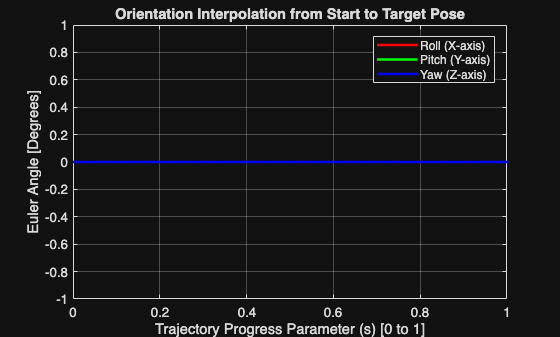

% Testing rotation interpolation

% --- 1. USER INPUTS ---
% Define your Start and Target Rotation Matrices.
% Here, Start is Identity, Target is a complex rotation (just to make the plot interesting)
R_start = eye(3);

% Let's do a 90 deg rotation around Z, and 45 deg around Y
R_target = [ 0.7071, -0.7071,  0.0000;
             0.7071,  0.7071,  0.0000;
             0.0000,  0.0000,  1.0000] * ...
           [ 0.7071,  0.0000,  0.7071;
             0.0000,  1.0000,  0.0000;
            -0.7071,  0.0000,  0.7071];

% --- 2. PRE-COMPUTATION (Done ONCE) ---
R_error = R_target * R_start';

tr = trace(R_error);
theta_total = acos( (tr - 1) / 2 );

if abs(theta_total) < 1e-6
    k = [0; 0; 1]; 
    theta_total = 0;
else
    k = (1 / (2 * sin(theta_total))) * ...
        [R_error(3,2) - R_error(2,3);
         R_error(1,3) - R_error(3,1);
         R_error(2,1) - R_error(1,2)];
end

% --- 3. TRAJECTORY GENERATION & PLOTTING ---
num_steps = 200; % Resolution of the plot
s_values = linspace(0, 1, num_steps);

% Pre-allocate arrays for the plot
roll_vals = zeros(1, num_steps);
pitch_vals = zeros(1, num_steps);
yaw_vals = zeros(1, num_steps);

% The skew-symmetric matrix 'K' from the axis 'k'
K = [  0,   -k(3),  k(2);
      k(3),   0,   -k(1);
     -k(2),  k(1),   0  ];

% Loop through the trajectory (simulating the 1000Hz loop)
for i = 1:num_steps
    s = s_values(i);
    
    % Scale the angle
    theta_current = theta_total * s;
    
    % Rodrigues' Formula
    R_delta = eye(3) + sin(theta_current)*K + (1 - cos(theta_current))*(K*K);
    R_current = R_delta * R_start;
    
    % Extract Euler Angles (Z-Y-X order / Yaw-Pitch-Roll) explicitly
    yaw_vals(i)   = atan2(R_current(2,1), R_current(1,1));
    pitch_vals(i) = atan2(-R_current(3,1), sqrt(R_current(3,2)^2 + R_current(3,3)^2));
    roll_vals(i)  = atan2(R_current(3,2), R_current(3,3));
end

% Convert radians to degrees for an easier-to-read plot
roll_deg = rad2deg(roll_vals);
pitch_deg = rad2deg(pitch_vals);
yaw_deg = rad2deg(yaw_vals);

% --- 4. CREATE THE PLOT ---
figure('Name', 'End-Effector Orientation Interpolation');
plot(s_values, roll_deg, 'r', 'LineWidth', 2); hold on;
plot(s_values, pitch_deg, 'g', 'LineWidth', 2);
plot(s_values, yaw_deg, 'b', 'LineWidth', 2);

% Formatting the plot
grid on;
title('Orientation Interpolation from Start to Target Pose');
xlabel('Trajectory Progress Parameter (s) [0 to 1]');
ylabel('Euler Angle [Degrees]');
legend('Roll (X-axis)', 'Pitch (Y-axis)', 'Yaw (Z-axis)', 'Location', 'best');
xlim([0 1]);